# **Free-Form Deformation (FFD) tutorial**

# **1. Bèzier curves**

## **1.1. Linear Bèzier curves**


$$0\le t\le 1$$



$$B\left(t\right)=\left(1−t\right)P_0 +tP_1$$


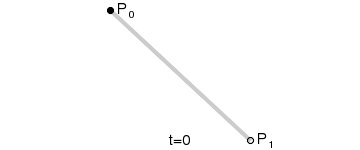

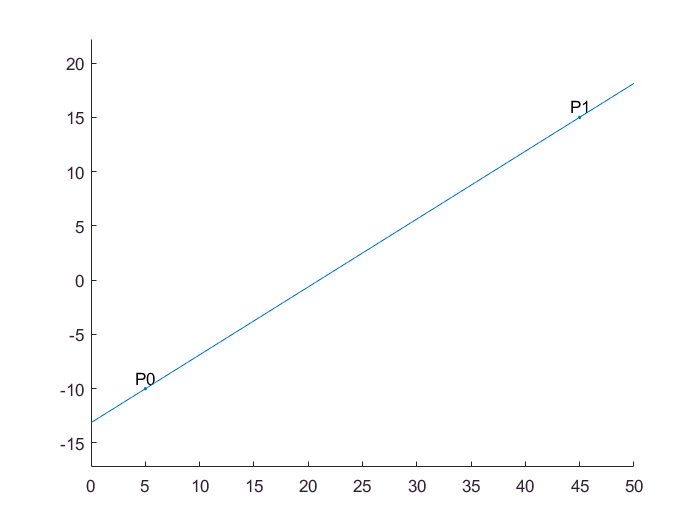

P0 = [ 5;-10];
P1 = [45; 15];

placelabel(P0,'P0');
placelabel(P1,'P1');
xlim([0 50])
axis equal

t = linspace(-1,2,101);
B = kron((1-t),P0) + kron(t,P1);

hold on
plot(B(1,:),B(2,:))
hold off

##  1.2. Quadratic Bèzier curves


$$B\left(t\right)=\sum_{i=0}^{n} b_{i,n} \left(t\right)P_i$$


where the polynomials


$$b_{i,n} \left(t\right)=$$

$$n \choose i$$
 
$$t^i {\left(1−t\right)}^{n−i} ,\text{  }i=0,\ldotp \ldotp \ldotp ,n$$


are known as ***Bernstein basis polynomials*** of degree $n$.

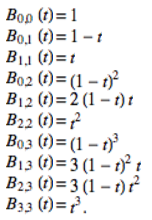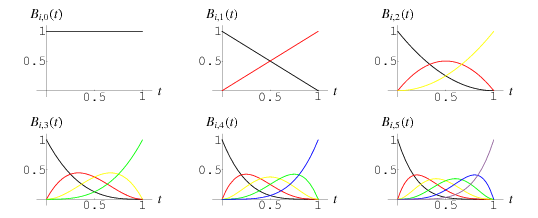


$$B\left(t\right)={\left(1−t\right)}^2 P_0 +2\left(1−t\right)tP_1 +t^2 P_2$$


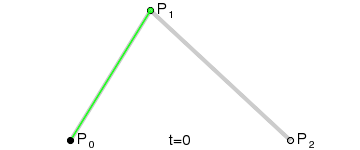

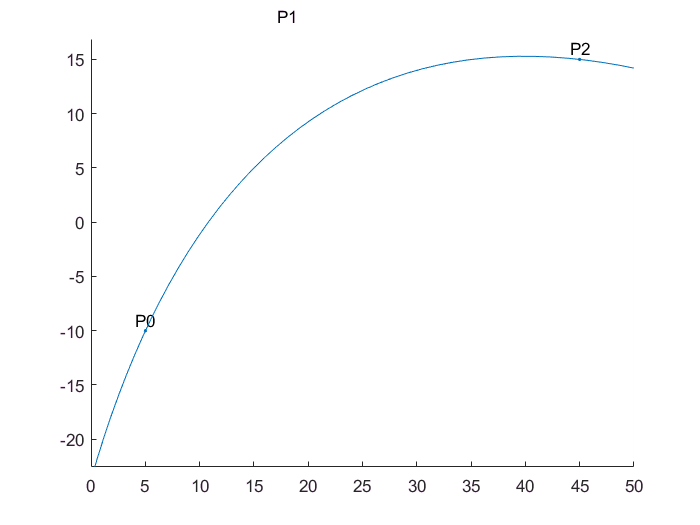

P0 = [ 5;-10];
P1 = [18; 18];
P2 = [45; 15];

cla
placelabel(P0,'P0');
placelabel(P1,'P1');
placelabel(P2,'P2');
xlim([0 50])
axis equal

B = kron((1-t).^2,P0) + kron(2*(1-t).*t,P1) + kron(t.^2,P2);

hold on
plot(B(1,:),B(2,:))
hold off

## 1.3. Cubic Bèzier


$$B\left(t\right)={{\left(1−t\right)}^3 P_o +3\left(1−t\right)}^2 P_1 +3\left(1−t\right)t^2 P_2 +t^3 P_3$$


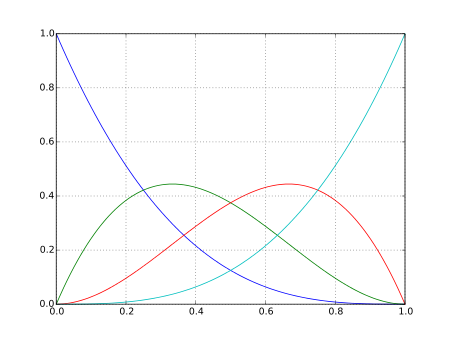

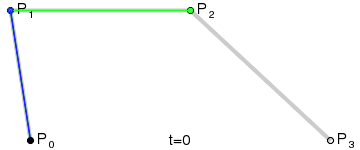

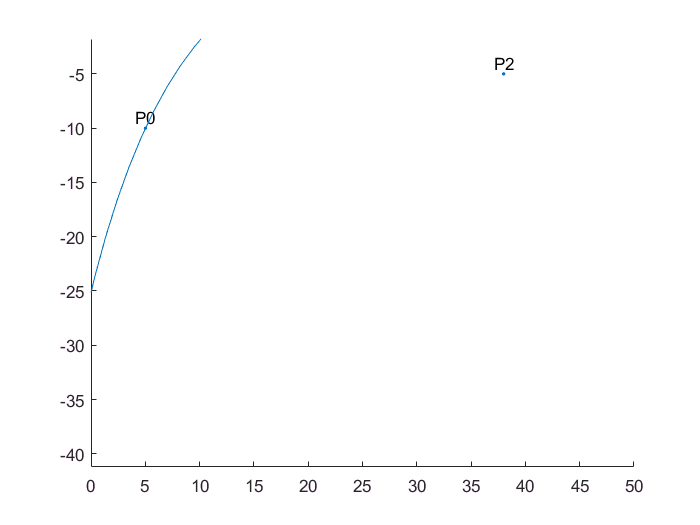

P0 = [ 5;-10];
P1 = [18; 18];
P2 = [38; -5];
P3 = [45; 15];

cla
placelabel(P0,'P0');
placelabel(P1,'P1');
placelabel(P2,'P2');
placelabel(P3,'P3');
xlim([0 50])
axis equal

B = kron((1-t).^3,P0) + kron(3*(1-t).^2.*t,P1) + kron(3*(1-t).*t.^2,P2) + kron(t.^3,P3);
hold on
plot(B(1,:),B(2,:))
hold off

##  1.4. Fifth-order Curves

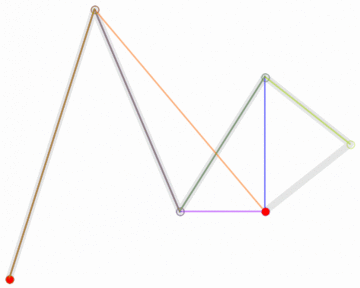

*Notice the pattern of the coefficients of the polynomials in these three examples.

- Order 1 - [1 1]

- Order 2 - [1 2 1]

- Order 3 - [1 3 3 1]

Binomial coefficients!

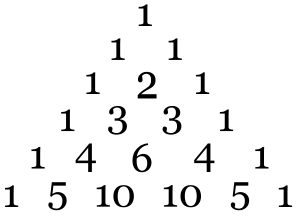

We can follow this pattern and create higher order Bèzier curves with more points.

# **2. Bèzier surfaces patches**

A given Bèzier surface of degree $\left(n,m\right)$ is defined by a set of $\left(n+1\right)\left(m+1\right)\text{ }$control points $P_{i,j}$. Bivariate tensor product


$$B\left(u,v\right)=\sum_{i=0}^{n} \sum_{j=0}^{m} b_{n,i} \left(u\right)b_{m,j} \left(v\right)P_{i,j} \text{  }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }0\le u,v\le 1$$


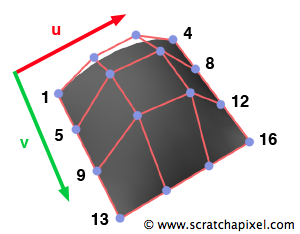     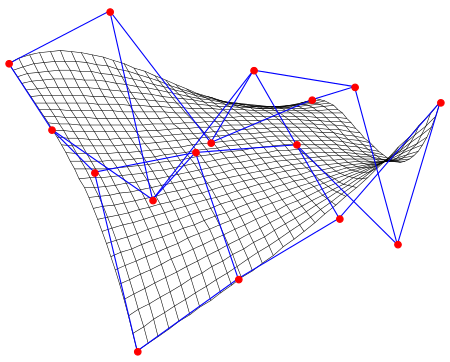

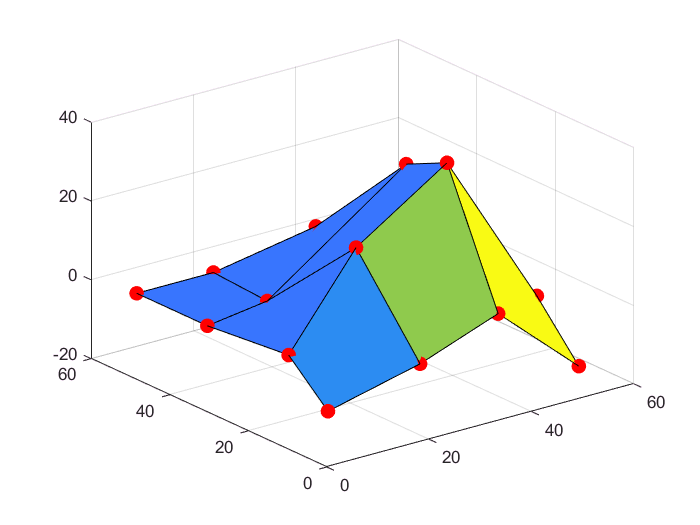

u = linspace(0,1,100);
v = u;

% surface of degree (3,3)
Px = [2, 17, 37, 51; 2, 16, 37, 51; 1, 18, 35, 51; 1, 19, 35, 50];
Py = [51, 51, 51, 51; 33, 36, 28, 33; 11, 16, 15, 13; 1 1, 2, 1];
Pz = [0,0,4.67,-6.67; 0,0,31,-0.96; 3,22,38,-0.47; -6.67, -0.96, 5.69, -12.46];

figure, surf(Px,Py,Pz), hold on
plot3(Px,Py,Pz,'.','MarkerSize',30,...
    'MarkerEdgeColor','r')

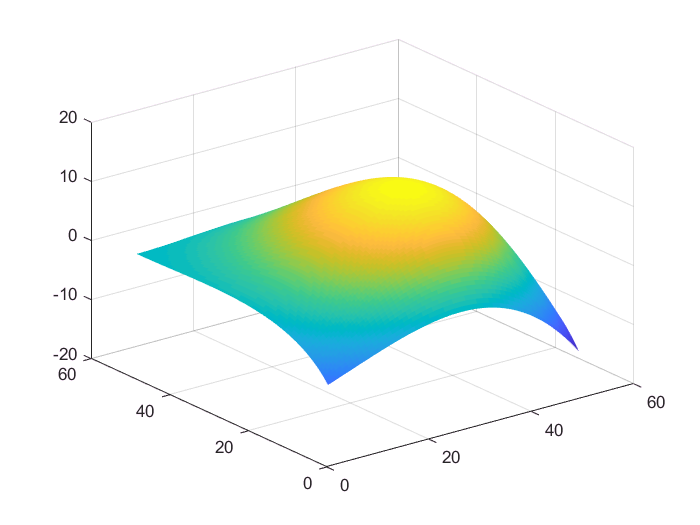


[x,y,z] = bezierSurface(Px,Py,Pz,u,v);

figure, surf(x,y,z);
shading flat

## The Utah teapot - 32 patches

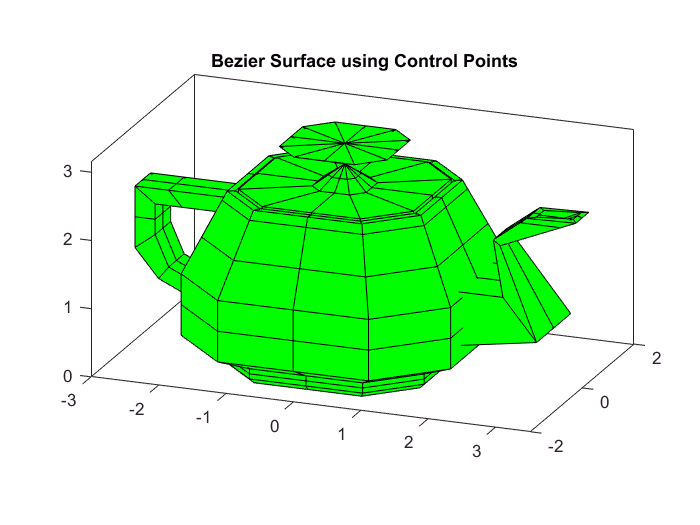

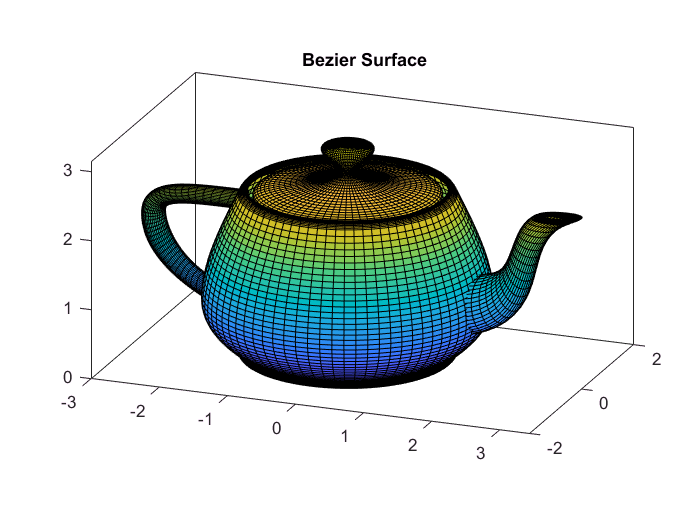

load('data\teapot'); 
[r, c, d, np] = size(S);

ni = 20; % number of interpolated values between end control points
u = linspace(0,1,ni); v = u; 
for k = 1:np
    Q(:,:,:,k) = bezierpatchinterp(S(:,:,:,k),u,v); % interpolation of kth patch
end

plotbeziersurface3D(S,Q)

# **3. FFD**

Mathematically, the FFD is defined in terms of a tensor product trivariate Bernstein polynomial. A FFD of degree $\left(l,m,n\right)$ is defined by a set of $\left(l+1\right)\left(m+1\right)\left(n+1\right)\text{ }$control points $P_{i,j,k}$.


$$B\left(u,v,w\right)=\sum_{i=0}^{l} \sum_{j=0}^{m} {\sum_{k=0}^{n} } b_{n,i} \left(u\right)b_{n,j} \left(v\right)b_{n,k} \left(w\right)P_{i,j,k} \text{  }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }0\le u,v,w\le 1$$


## 3.1. Imposing a local coordinate system on a parallelpiped region

Any point $X$has $\left(s,t,u\right)$coordinates in this system such that


$$X=X_o +sS+tT+uU\ldotp$$


The $\left(s,t,u\right)$coordinates of $X$can easily by


$$s=\frac{T\times U\left(X−X_o \right)}{T\times U\cdot S},\text{         }t=\frac{S\times U\left(X−X_o \right)}{S\times U\cdot T},\text{        }u=\frac{U\times T\left(X−X_o \right)}{S\times T\cdot U},\text{          }0\le s,t,u\le 1$$


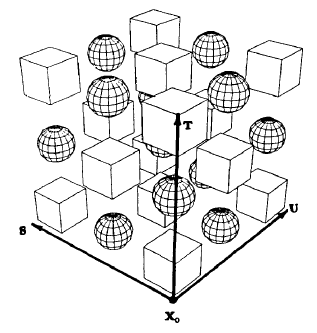

## 3.2. Imposing a grid of control points $P_{i,j,k}$ on the paralellpiped

E.g. $l,m,n\text{ }=3$

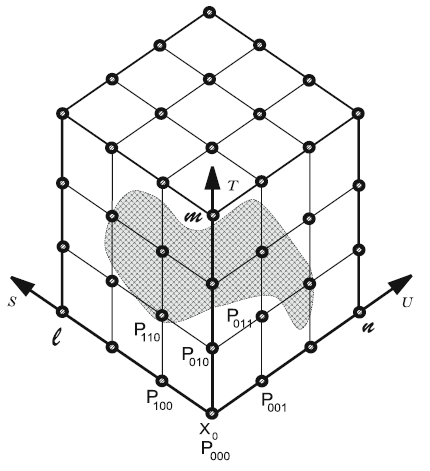

The location of the control points which lie on the lattice are defined as


$$P_{i,j,k} =X_o +\frac{i}{l}S+\frac{j}{m}T+\frac{k}{n}U\ldotp$$


## 3.3. Deformation

The deformation is specified by moving the $P_{i,j,k}$ control point. The deformation function i defined by a trivariate tensor product Bernstein polynomial. The deformed position $X_{ffd}$of an arbitraty point $X$is found by

- Computing its $\left(s,t,u\right)$coordinates

- Evaluating the deformation function


$$X_{\text{ffd}} \left(s,t,u\right)=\sum_{i=0}^{l} \sum_{j=0}^{m} \sum_{k=0}^{n} b_{l,i} \left(s\right)b_{m,j} \left(t\right)b_{n,k} \left(u\right)P_{i,j,k} \text{  }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }0\le s,t,u\le 1$$


where $X_{ffd}$is a vector containing the Cartesian coordinates of the displaced point, and $P_{i,j,k}$is a vector containing the Cartesian coordinates of the control point.

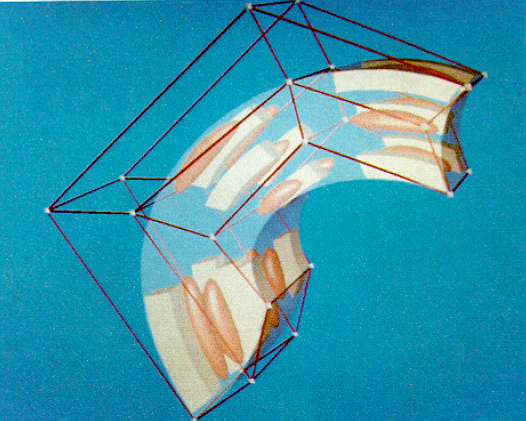

The 12 edges of the pararellpiped are actually mapped into Bèzier curves, defined by the control points that initially lie on the respective edges. Also, the 6 planar faces map into tensor product Bèzier surface patches, defined by the control points which initially lie on the respective faces.

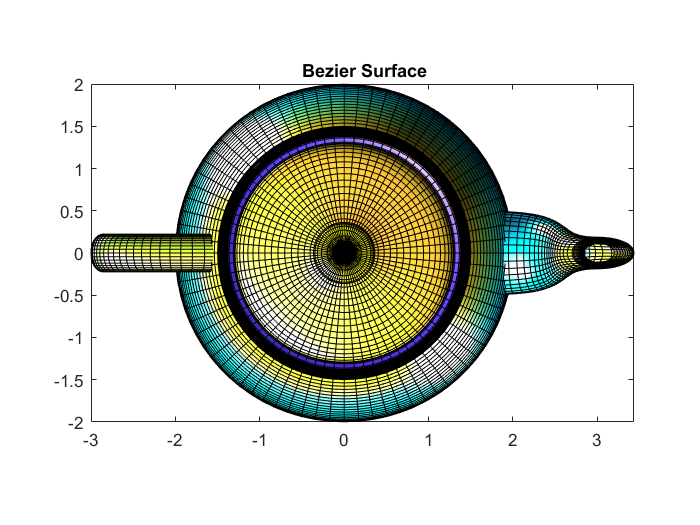

%% load CAD model
load('data\bunny.mat');
dataCAD = bunny;

%% get min-max coordinates
meshInfo = get_mesh_info(dataCAD);
show_cad_model(meshInfo.vertices, meshInfo.faces)
view([-0.4474 90.0000])


%% init the FFD axis - STU coordinate system
ffdObj = ClassFFD;
ffdCoord = ffdObj.initAxes(meshInfo);

%% create the grid of control points (lattice)
% set the number of planes - l+1, m+1, n+1
l = 3;
m = 3;
n = 3;
lattice = ffdObj.initControlLattice(ffdCoord, l, m, n);

%% set manually a control point and its new coordinate to be deformed
% control point?
i = 1; %1 3
j = 4; %4 1
k = 1; %1 2
% new coordinate?
lattice(i,j,k).x = -0.2; %-0.2
lattice(i,j,k).y = 0.2;  %0.2
lattice(i,j,k).z = -0.2; %-0.2

%% perform the FFD deformation - IT WILL TAKE ABOUT A MINUTE TO RUN!
vertDeformed = deform_mesh(meshInfo, ffdCoord, lattice, l, m, n);

Deforming model...
Done in 78.16 s!


Output argument "vertDeformed" (and maybe others) not assigned during call to "deform_mesh".

show_cad_model(vertDeformed, dataCAD.faces)
view([-0.447 90.000])

# **4. Direct FFD**

"Move *this* point of the object to *there*” and finds control point positions that will effect this action.


$$X_{\text{ffd}} \left(s,t,u\right)=\sum_{i=0}^{l} \sum_{j=0}^{m} \sum_{k=0}^{n} b_{n,i} \left(s\right)b_{n,j} \left(t\right)b_{n,k} \left(u\right)P_{i,j,k} \text{  }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }0\le s,t,u\le 1$$



$$X_{ffd} =BP$$



$$P=B^{\dagger } X_{ffd}$$


% 3D mesh vertices
Xffd = meshInfo.vertices;

% compute B (numV X numCP) - Bernstein basis matrix / Deformation matrix
B = get_deformation_matrix(meshInfo, ffdCoord, l, m, n);

% Direct FFD - compute P that makes that deformation
% deform a single point in the mesh
% Xffd(32649, 1) = 5;
% Xffd(11617, 1) = 10;
% Xffd(11617, 2) = 10;
Xffd(32322, 1) = 2;
Xffd(32322, 2) = 2;

%P = pinv(B) * Xffd;
P = B \ Xffd;
%figure, plot3(P(:,1),P(:,2),P(:,3),'.')
Xffd_new = B * P;

% show new deformation
show_cad_model(Xffd_new, dataCAD.faces)
view([-0.4474 90.0000])